# DEMO for Cartesian 2D SENSE 

This is a demo to play around with certain factors involved in the most simplistic Cartesian SENSE reconstruction. The simulations are performed on the shepp-logan phantom or brain images. MAKE SURE YOU ARE IN THE DIRECTORY: "/Sense_educational/" 

Tom Bruijnen 20170625

## Set input parameters for the simulations

All these parameters are adjustable, only NC & M have to be integers

% Empty workspace
clear all;clc;echo off
addpath(genpath(pwd))

% If you would rather have a brain image to look at set the parameter below to 1.
brain=0;

NC=8;           % Number of receive coils 
M=128;          % Matrix size of image 
csm_sigma=3.5;    % Width of gaussian coil sensitivity profiles
R=4;          % Undersampling factor 

% Some noise characteristics, note that these affect the results a lot
noise_sampling=.0005;         % Noise on samples % of kmax
noise_csm=.01;               % Noise on acquired csm % of Imax

% Check input parameters 
NC=round(NC);
M=makedyadic(M);   % Make M 2^n
R=makedyadic(R);   % Make R 2^n


## Create phantom and coil sensitivity maps

Create the phantom and coil sensitivity maps without any noise

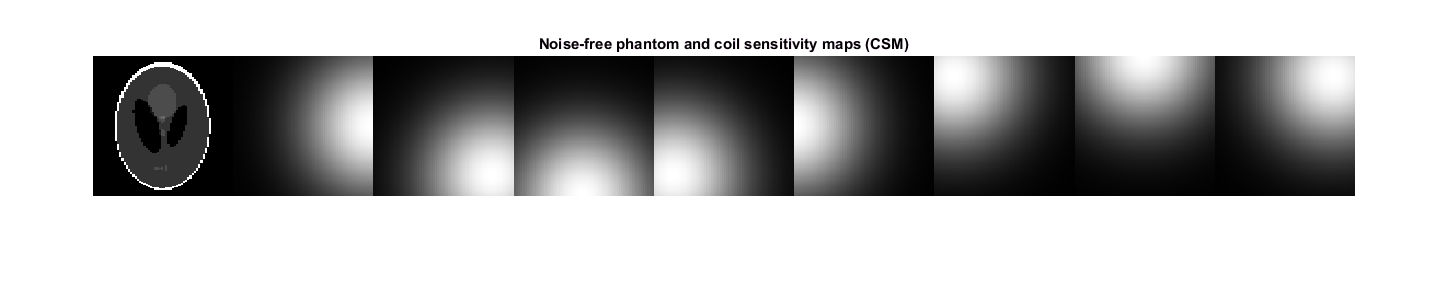

% Create shepp-logan phantom
x_true=phantom(M);

% If you wanted the brain phantom, do some interpolation 
if brain;load brain;[x1,y1]=meshgrid(1:512,1:512);[x2,y2]=meshgrid(1:M,1:M);
    x_true=interp2(x1,y1,abs(x_true),512/M*x2,512/M*y2,'spline');end

% Generate Gaussian shaped coil sensitivity maps
csm=generate_csm(NC,M,csm_sigma);

% Visualization
figure(1);imshow3(abs(cat(3,x_true,csm)),[],[1 (1+NC)]);
set(gcf,'Position',[0 0 1450 300]);
title('Noise-free phantom and coil sensitivity maps (CSM)');

## Why does the classical sense formalism work for cartesian sampling?

Lets examine the corresponding point-spread-function (PSF). This simply means that we perform an experiment where we put all ones on our samples and mimic undersampling by entering zero values at specific phase encoding lines. These type of experiments provide a lot of knowledge how energies are distributed across multiple pixels. We will do this for a number of undersampling factors. Note that it is handy to know that when all spatial frequency have equal amplitude and equal phase the corresponding image is a point. This is analogous to the Fourier transform of a dirac pulse which is a flat frequency spectrum.

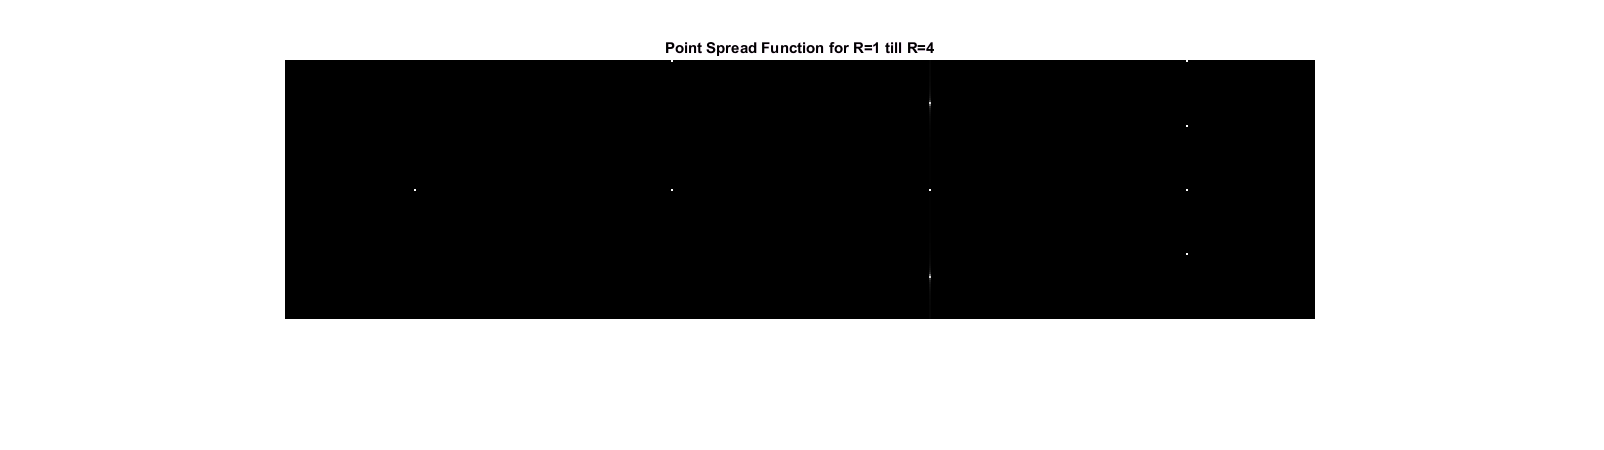

% Lets examine the point spread function (PSF) for a couple of undersampled cartesian acquisitions. 
% Dont bother about the syntax for now, only the result is important.
for Rn=1:4                   % Undersampling factor
    K_psf=zeros(M,M);        % K-space samples
    K_psf(1:Rn:end,:)=1;     % Uniform undersampling
    I_psf(:,:,Rn)=fftshift(ifft2(ifftshift(K_psf)))*Rn;  % 2D Fast inverse Fourier Transform
end

figure(2),imshow3(abs(I_psf),[],[1 4]);
set(gcf,'Position',[0 0 1.5*1450 1.5*300]);
title('Point Spread Function for R=1 till R=4');

You can observe that the energy gets folded over multiple pixels in the image domain. What is also apparent is that it gets folded over exactly R pixels in these cases. If you look very closely you will notice that for the case when R=3 the energy distribution is actually slightly different, this is simple due to the fact that M/R does not equal an integer and therefore my implementation performs suboptimal sampling. Now that we know how the energy if each pixels gets folded we also know how to unfold the energy!

## Lets mimic the MR experiment

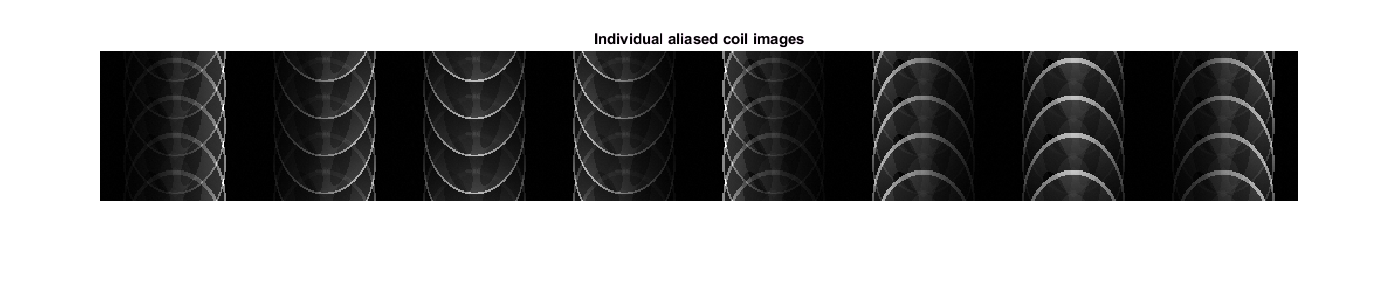

% We take our phantom image (x_true), multiply it with the coil sensitivity maps and subsequently perform a Fourier transform.
y=ifftshift(fft2(fftshift(repmat(x_true,[1 1 NC]).*csm)));

% Lets mimic real-live condition which include noise on the measurements
% First define a function to add gaussian complex noise
add_noise=@(x,lvl)(x+lvl*randn(size(x))+1j*lvl*randn(size(x)));

% Add noise to our measurements "y"
y=add_noise(y/max(abs(y(:))),noise_sampling);

% Add noise to our measured coil sensitivity maps
csm=add_noise(csm,noise_csm);

% Perform the undersampling with factor R by zerofilling lines (uniform
% fashion but keep the center line of k-space)
y_us=zeros(size(y));
idx=sort([floor(M/2)-R+1:-R:1 floor(M/2)+1:R:M]);
y_us(idx,:,:)=y(idx,:,:); % y_us = y undersampled

% Perform an inverse fourier transform on the undersampled and noisy data
x_folded=fftshift(ifft2(ifftshift(y_us)));

% Visualization
figure(3),imshow3(abs(cat(3,x_folded/max(abs(x_folded(:))))),[],[1 NC]);
set(gcf,'Position',[0 0 1400 300]);
title('Individual aliased coil images');

Now lets examine the individual aliased coil images. You can observe that every receive channel exhibits different degrees of aliasing. This is the principle we use to unfold the images.

## Lets perform the unfolding according to the theory below

Now that we have our aliased multi-coil images and the corresponding spatial sensitivities we can try to unfold them according to the method described by Pruessman et al. This method is generally referred to as cartesian sense and is the easiest and least computational method to perform parallel imaging. The method is completely based on the observation we made in the previous cells that the folding of the energy can be predicted and is completely dependent on the sampling pattern employed.  The governing equation from the article (also shown in the video) is the following one:$p={\left(S^H \psi^{-1} S\right)}^{-1} \left(S^H \psi^{-1} \mathbf{m}\right)$  with the following parameters. Here $\psi$ is the noise covariance matrix, which indicates correlated noise across multiple receivers. In our simulations we gave all the receivers similar uncorrelated noise, thus this reduces to the identity matrix $\left(I\right)$ and can be left out : $p={\left(S^H S\right)}^{-1} \left(S^H \mathbf{m}\right)$. Further $S^H$ is the conjugate transpose of the sensitivity matrix.

    p = unfolded pixel value 

    S = [R x NC] matrix containing the spatial sensitivities for R folded pixel locations and NC receivers

    **m** = [NC x 1] matrix containing the measured intensities per receiver 

In words this equation results into calculating the pseudo-inverse of the (potentially) non-square matrix S and multiplying it with the measured values **m**

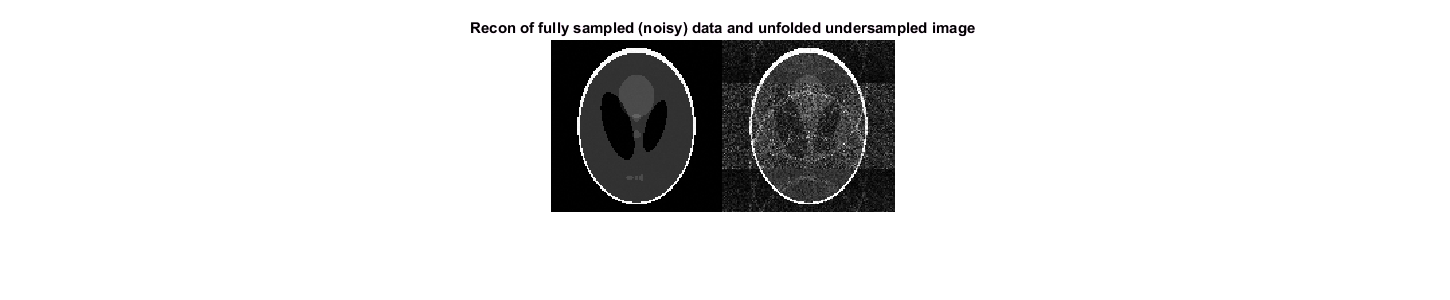

% Preallocate unfolded matrix p
p=zeros(M);

% Assign aliasing distance from PSF
dx=M/R;

% Loop over all pixels and perform the inversion described above
% remember that we performed the undersampling in the X-dimension
for px=1:M/R
    % Calculate coordinates where aliasing is on (known from the PSF)
    coords=mod(px+((1:R)-1).*dx-1,M)+1;
    for py=1:M
        % Generate vector m from equation (1)
        m=permute(x_folded(px,py,:),[3 1 2]);
        % Generate matrix S 
        S=permute(csm(coords,py,:),[3 1 2]);
        % Do inversion to unfold
        p(coords,py)=pinv(S)*m;
    end
end

% Visualization
tmp=fftshift(ifft2(ifftshift(y)));
true=abs(sum(conj(csm).*tmp,3))./sum(abs(csm).^2,3); % Combine coils
figure(4),imshow3(cat(3,true/max(abs(true(:))),abs(p/prctile(abs(p(:)),97.5))),[0 1],[1 2]);
set(gcf,'Position',[0 0 1450 300]);
title('Recon of fully sampled (noisy) data and unfolded undersampled image');

## Why does the unfolding fail dramatically for higher accelerations (R~NC)?

The matrix $S$ has to be inverted. When this is ill-conditioned, i.e. when the rows or colums of the matrix are not independent anymore (matrix is singular). In a physical context this would be when there is barely any difference in spatial sensitivities between the aliased pixels across multiple receivers. With the implementation shown in the previous the pseudo inverse of the matrix breaks down and doesnt provide any usefull output anymore. One solution for this is to constrain the solution of the inversion of the matrix. This is often referred to as a regularized matrix inversion, this is what I believe the scanner reconstruction does as well. The most simplest form of regularization is zeroth order Tikhonov. 

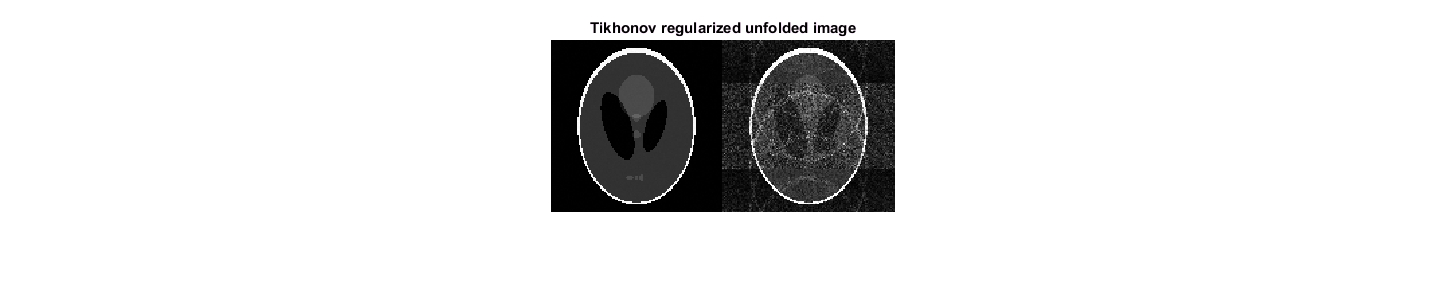

% Preallocate unfolded matrix p
p=zeros(M);

% Assign aliasing distance from PSF
dx=M/R;

% Regularization parameter
lambda=0.0001;

% Loop over all pixels and perform the inversion described above
% remember that we performed the undersampling in the X-dimension
for px=1:M
    % Calculate coordinates where aliasing is on (known from the PSF)
    coords=mod(px+((1:R)-1).*dx-1,M)+1;
    for py=1:M
        % Generate vector m from equation (1)
        m=permute(x_folded(px,py,:),[3 1 2]);
        % Generate matrix S 
        S=permute(csm(coords,py,:),[3 1 2]);
        % Prepare data for regularization
        SHS=conj(transpose(S))*S;
        red_eye=diag(abs(diag(SHS))>0);
        n_alias=sum(red_eye(:));
        regularization=lambda*trace(SHS)/n_alias;
        % Do inversion to unfold
        p(px,py)=pinv(SHS+red_eye.*regularization)*conj(transpose(S))*m;
    end
end

% Visualization
tmp=fftshift(ifft2(ifftshift(y)));
true=abs(sum(conj(csm).*tmp,3))./sum(abs(csm).^2,3); % Combine coils
figure(4),imshow3(cat(3,true/max(abs(true(:))),abs(p/prctile(abs(p(:)),97.5))),[0 1],[1 2]);
set(gcf,'Position',[0 0 1450 300]);
title('Tikhonov regularized unfolded image');



% END